% ========================================================
% === SCRIPT COMPLETO: AUTOENCODER SU VOLTI ORL    ===
% ========================================================
clear; clc; close all;
rng(0);
tic;

%% ----------------------------------------------------------------
%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
%% ----------------------------------------------------------------
projectRoot  = pwd;  % o percorso personalizzato
addpath(genpath(projectRoot));
results_path = fullfile(pwd,'results_orl_ae');
if ~exist(results_path,'dir')
    mkdir(results_path);
end

%% ----------------------------------------------------------------
%% 1) PARAMETRI AUTOENCODER
%% ----------------------------------------------------------------
epochs        = 50;
learning_rate = 0.01;
bottleneck    = 40;
train_ratio   = 0.8;

%% ----------------------------------------------------------------
%% 2) CARICAMENTO DATASET ORL & PREPROCESSING
%% ----------------------------------------------------------------
fprintf('>>> Caricamento dataset ORL...\n');

>>> Caricamento dataset ORL...


load('dataset/volti_dataset.mat');  % A (m×n)
A = double(A) / 255;

[m, n] = size(A);
img_h = 112; img_w = 92;

%% ----------------------------------------------------------------
%% 3) CALCOLO VISO MEDIO E CENTRATURA
%% ----------------------------------------------------------------
mean_face   = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
A_centered  = A - mean_face;

%% ----------------------------------------------------------------
%% 4) FLATTEN DEI PIXEL
%% ----------------------------------------------------------------
X_all = A_centered';    % [n_samples×m]

%% ----------------------------------------------------------------
%% 5) SPLIT TRAIN/TEST (80/20)
%% ----------------------------------------------------------------
perm     = randperm(n);
n_train  = round(train_ratio * n);
train_idx = perm(1:n_train);
test_idx  = perm(n_train+1:end);
X_train   = X_all(train_idx, :);
X_test    = X_all(test_idx,  :);
orig_idx_test = test_idx;

%% ----------------------------------------------------------------
%% 6) TRAINING AUTOENCODER
%% ----------------------------------------------------------------
fprintf('>>> Training autoencoder sui pixel (bottleneck=%d)...\n', bottleneck);

>>> Training autoencoder sui pixel (bottleneck=40)...


[W_enc, b_enc, W_dec, b_dec, loss_tr, loss_te] = ...
    autoencoder_train(X_train, X_test, mean_face, bottleneck, epochs, learning_rate);

[AE] Epoca  10/ 50: Train MSE=0.02664, Test MSE=0.02979
[AE] Epoca  20/ 50: Train MSE=0.02610, Test MSE=0.02891
[AE] Epoca  30/ 50: Train MSE=0.02604, Test MSE=0.02871
[AE] Epoca  40/ 50: Train MSE=0.02602, Test MSE=0.02864
[AE] Epoca  50/ 50: Train MSE=0.02602, Test MSE=0.02862


save(fullfile(results_path,'ae_orl_weights.mat'),'W_enc','b_enc','W_dec','b_dec','loss_tr','loss_te');

%% ----------------------------------------------------------------
%% 7) VALUTAZIONE SUL TEST SET (MSE pixel)
%% ----------------------------------------------------------------
n_test    = numel(orig_idx_test);
mse_pixel = zeros(n_test,1);
for i = 1:n_test
    idx = orig_idx_test(i);
    x_in = X_all(idx, :)';                    % [m×1] centrato
    h    = max(0, W_enc * x_in + b_enc);      % encoding + ReLU
    x_hat_centered = W_dec * h + b_dec;       % [m×1]
    x_rec = x_hat_centered + mean_face;      % ricostruzione pixel
    x_orig = A(:, idx);                      % originale non centrato
    err = x_orig - x_rec;
    mse_pixel(i) = mean(err.^2);
end
mean_mse = mean(mse_pixel);
fprintf('>>> MSE medio pixel su test set: %.6f\n', mean_mse);

>>> MSE medio pixel su test set: 0.028619


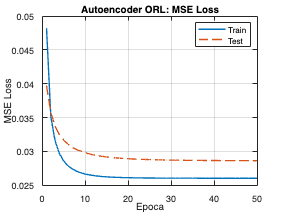


%% ----------------------------------------------------------------
%% 8) PLOT DELL’ANDAMENTO DELLA LOSS
%% ----------------------------------------------------------------
figure('Name','AE ORL: Train vs Test MSE');
plot(1:epochs, loss_tr,'-','LineWidth',1.5); hold on;
plot(1:epochs, loss_te,'--','LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss');
legend('Train','Test','Location','northeast');
title('Autoencoder ORL: MSE Loss');
grid on;
saveas(gcf, fullfile(results_path,'ae_orl_loss.png'));

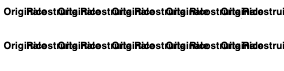


%% ----------------------------------------------------------------
%% 9) VISUALIZZAZIONE RICOSTRUZIONI (TEST)
%% ----------------------------------------------------------------
num_show = 10;
sel      = randperm(n_test, num_show);
figure('Name','AE ORL: Ricostruzioni','Position',[50,50,120*num_show,300]);
tiledlayout(2,num_show,'Padding','compact','TileSpacing','compact');
for i = 1:num_show
    idx = orig_idx_test(sel(i));
    orig_img = reshape(A(:,idx), img_h, img_w);
    x_in     = X_all(idx, :)';
    h        = max(0, W_enc * x_in + b_enc);
    x_hat_c  = W_dec * h + b_dec;
    rec_img  = reshape(x_hat_c + mean_face, img_h, img_w);
    nexttile;
    imshow(orig_img,[]); title('Originale');
    nexttile;
    imshow(rec_img,[]); title('Ricostruita');
end
saveas(gcf, fullfile(results_path,'ae_orl_recon.png'));


fprintf('>>> Fine script (%.2f s)\n', toc);

>>> Fine script (50.05 s)
